# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 27-Oct-2020 01:00:29

## Setup the Import Options

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["city", "city_ascii", "lat", "lng", "country", "Var6", "Var7", "Var8", "capital", "population", "Var11"];
opts.SelectedVariableNames = ["city", "city_ascii", "lat", "lng", "country", "capital", "population"];
opts.VariableTypes = ["string", "string", "double", "double", "categorical", "string", "string", "string", "categorical", "double", "string"];
opts = setvaropts(opts, [1, 2, 6, 7, 8, 11], "WhitespaceRule", "preserve");
opts = setvaropts(opts, [1, 2, 5, 6, 7, 8, 9, 11], "EmptyFieldRule", "auto");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
worldcities = readtable("F:\16.IUT\summer_2020\EEE 4416\Matlab\worldcities.csv", opts);
worldcities(1,:)=[]

worldcities = 26562×7 table
        city          city_ascii        lat        lng         country         capital      population
    _____________    _____________    _______    _______    _____________    ___________    __________

    "Tokyo"          "Tokyo"            35.69     139.69    Japan            primary        3.7977e+07
    "Jakarta"        "Jakarta"        -6.2146     106.85    Indonesia        primary         3.454e+07
    "Delhi"          "Delhi"            28.66      77.23    India            admin          2.9617e+07
    "Mumbai"         "Mumbai"          18.967     72.833    India            admin          2.3355e+07
    "Manila"         "Manila"          14.596     120.98    Philippines      primary        2.3088e+07
    "Shangha

- u've to generate livescript by urself. running this code wont work.

- but u can see the answers and try them out by urself in ur own mlx file.

- If you look carefully, i didn't import all columns. I only imported the ones I need.

- use ctrl to select the columns u wanna import.

q1=worldcities.country

q1 = 26562×1 categorical array
     Japan 
     Indonesia 
     India 
     India 
     Philippines 
     China 
     Brazil 
     Korea, South 
     Mexico 
     China 
     China 
     Egypt 
     United States 
     India 
     Russia 
     Thailand 
     Argentina 
     China 
     Bangladesh 
     Nigeria 
     Turkey 
     Japan 
     Pakistan 
     India 
     Iran 
     Congo (Kinshasa) 
     Vietnam 
     United States 
     Brazil 
     China 
     India 
     China 
     Pakistan 
     France 
     United Kingdom 
     China 
     China 
     China 
     China 
     China 
     Peru 
     India 
     Colombia 
     China 
     Japan 
     China 
     China 
     China 
     China 
     United States 
     China 
     Angola 
     China 
     Malaysia 
     China 
     China 
     Vietnam 
     India 
     China 
     China 
     China 
     China 
     Nigeria 
     China 
     China 
     India 
     Hong Kong 
     Sudan 
     China 
     China 
     China 
     China 
   

length(unique(q1))

ans = 223

q2=worldcities.population>10000000;
sum(q2)

ans = 39

q3=worldcities.population>5000000;
q33=worldcities(q3,:)

q33 = 146×7 table
        city          city_ascii        lat        lng         country         capital      population
    _____________    _____________    _______    _______    _____________    ___________    __________

    "Tokyo"          "Tokyo"            35.69     139.69    Japan            primary        3.7977e+07
    "Jakarta"        "Jakarta"        -6.2146     106.85    Indonesia        primary         3.454e+07
    "Delhi"          "Delhi"            28.66      77.23    India            admin          2.9617e+07
    "Mumbai"         "Mumbai"          18.967     72.833    India            admin          2.3355e+07
    "Manila"         "Manila"          14.596     120.98    Philippines      primary        2.3088e+07
    "Shanghai"       "

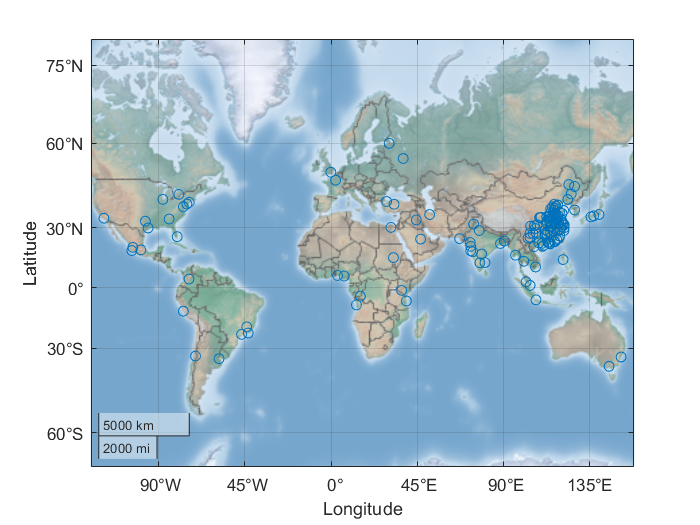

geoscatter(q33.lat,q33.lng)
geobasemap colorterrain

q5= worldcities.country=="Bangladesh"

q5 = 26562×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


worldcities(q5,:)

ans = 18×7 table
          city            city_ascii       lat       lng       country        capital      population
    ________________    ______________    ______    ______    __________    ___________    __________

    "Dhaka"             "Dhaka"           23.716    90.396    Bangladesh    primary        1.5443e+07
    "Chattogram"        "Chattogram"      22.335    91.832    Bangladesh    admin          2.5816e+06
    "Khulna"            "Khulna"          22.817     89.55    Bangladesh    admin          1.3111e+06
    "Sylhet"            "Sylhet"            24.9    91.867    Bangladesh    admin          4.7984e+05
    "RÄjshÄhi"        "Rajshahi"        24.367      88.6    Bangladesh    admin          4.4809e+05
    "Comilla"           "Comilla